# Random Path (rPath)

This program demonstrates random waypoint mobility with k-anonymity logic integrated. During the simulation drone will navigate through a set of waypoints visited dummy waypoints to obscure its trajectory. The program was written by Josh Josey with help and code snippets from examples within the UAV toolbox documentation.

### **Define the simulation variables**

Px = 6; Py = 6; Pz = 6.5;       %Proportional Coeffecients
Dx = 1.5; Dy = 1.5; Dz = 2.5;   %Derivative Coeffecients
Ix = 0; Iy = 0; Iz = 0;         %Integral Coeffecients
Nx = 1.25*10; Ny = 1.25*10; Nz = 1.25*14.4947065605712; %Filter Coefficients
Gravity = 9.81;
DroneMass = 0.1;
UAVSampleTime = 0.01;
runtime = 75; %max runtime for time based simulations
missionLength = 5; %max waypoints visited for length based simulations
escapeMargin = 1; %safety buffer when exiting a restricted area
useObstacleAvoidance = 0; 
numDummies = 2; %number of dummy points to visit

### Create a UAV scenario & platform

hold off
Scenario = uavScenario("UpdateRate",100,"ReferenceLocation",[0 0 0]);

%mark the starting location
InitialPosition = [0 0 0];
takeoffWP = [0 0 -15];
InitialOrientation = [0 0 0];

%create the initial waypoints based on the number of dummies
InitialWPS = zeros(numDummies+2,3);
[sz,~] = size(InitialWPS);
%set the first value to the initial position
InitialWPS(1,:) = InitialPosition;
%set the intermediate values to increment closer to the first pt
for i=2:sz-1
    InitialWPS(i,:) = [InitialPosition(1) InitialPosition(2) takeoffWP(3)*(i)/(sz)];
end
%add in the takeoff waypoint
InitialWPS(end,:) = takeoffWP;

%plot the initial position
addMesh(Scenario,"cylinder",{[InitialPosition(2) InitialPosition(1) 1] [0 .01]},[0 1 1]);  

%create a UAV model in the scenario
platUAV = uavPlatform("UAV",Scenario, ...
                    "ReferenceFrame","ENU", ...
                    "InitialPosition",InitialPosition, ...
                    "InitialOrientation",eul2quat(InitialOrientation));

%add the drone mesh over the model (style,size,color,orientation)
updateMesh(platUAV,"quadrotor",{1},[1 0 1],eul2tform([0 0 pi]));

### Add in obstacles

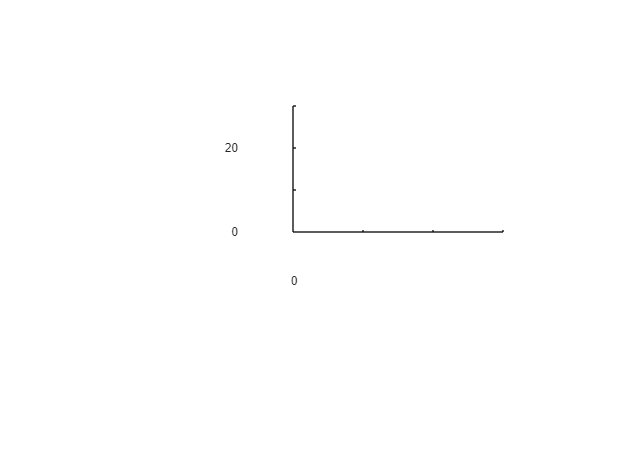

if useObstacleAvoidance == 1
    %Obstacle locations & dimensions
    if restricted_area_ct >= 1
        obstaclePos = [5 25 0; 25 25 0; 25 5 0];%[5 5 0;5 25 0; 25 25 0; 25 5 0];
    else
        obstaclePos = [15 15 0];
    end
    obstacleHeight = 15;
    obstacleWidth = 5;
    
    %create an obstacle struct for passing to functions
    obs.Pos = obstaclePos;
    obs.Height = obstacleHeight;
    obs.Width = obstacleWidth;

    %plot the obstacles
    for i = 1:size(obstaclePos,1)
        addMesh(Scenario, "polygon", ...
                {  %the sides of the obstacle
                   [obstaclePos(i,1)-obstacleWidth/2 obstaclePos(i,2)-obstacleWidth/2;
                    obstaclePos(i,1)+obstacleWidth/2 obstaclePos(i,2)-obstacleWidth/2;
                    obstaclePos(i,1)+obstacleWidth/2 obstaclePos(i,2)+obstacleWidth/2;
                    obstaclePos(i,1)-obstacleWidth/2 obstaclePos(i,2)+obstacleWidth/2;],
                   %the height of the obstacle
                   [obstaclePos(i,3) obstaclePos(i,3)+obstacleHeight]
                },[1 .3 0]);
    end
end

xlim([0 30]);  
ylim([0 30]);

### Run the simulation and extract data

out = sim("rPath.slx");

%extract the drones trajectory
points = squeeze(out.trajectoryPoints(1,:,:))';

%extract the waypoints
Waypoints = squeeze(out.waypoints)';
Waypoints = unique(Waypoints, 'rows','stable');

%--extract the dummies
Dummies = out.dummyLog;
%get the size of the dummy log 3rd dimension
sz = size(Dummies, 3);
%create a copy of the placeholder Array
placeholderArray = zeros(numDummies,3);

% Initialize an array to store where real dummies are located
realDummies = true(1, sz);

% compare each Nx3 array and mark the placeholder arrays
for i = 1:sz
    % If the slice is equal to the zeroSlice, mark it for removal
    if isequal(Dummies(:,:,i), placeholderArray)
        realDummies(i) = false;
    end
end

% Remove the placeholder values
Dummies = Dummies(:,:,realDummies);

     5

MISSION DONE


### Plot the waypoints & trajectory

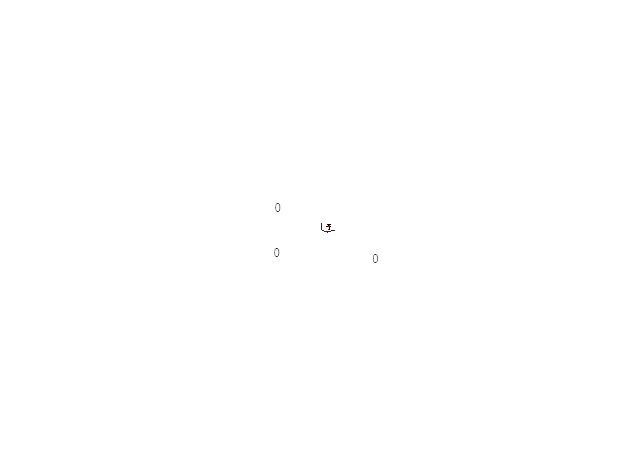

clf;
hold on;
sz = size(Waypoints,1);
%generate a color mapping for each waypoint
colors = zeros(sz,3);
[X,Y,Z] = sphere;

%plot the real waypoints
for i = 1:size(Waypoints,1)
    colors(i,:) = [rand() rand() rand()];
    surf(X+Waypoints(i,2), Y+Waypoints(i,1), Z-Waypoints(i,3),'FaceAlpha',0.5,'EdgeColor','none','FaceColor',colors(i,:))
end

%plot the dummy points
Xd = X/2;
Yd = Y/2;
Zd = Z/2;
for i = 1:size(Dummies,3)
    for j = 1:size(Dummies,1)
        surf(Xd+Dummies(j,2,i), Yd+Dummies(j,1,i), Zd-Dummies(j,3,i),'FaceAlpha',0.3,'EdgeColor','none','FaceColor',colors(i,:))
    end
end


%plot the straight line path between points (RED)
plot3([InitialPosition(1,2); Waypoints(:,2)],[InitialPosition(1,2); Waypoints(:,1)],[-InitialPosition(1,3); -Waypoints(:,3)],"-r");

%plot the trajectory (BLACK)
plot3(points(:,2),points(:,1),-points(:,3),"-k");

show3D(Scenario);

### Simulation Report

disp("Simulation Report ---")
str = 'Total Time: '; value = out.tout(end); fprintf('%s %.3f\n', str, value);

slDist = 0;
for i = 1:size(Waypoints)-1
        slDist = slDist + sqrt(sum((Waypoints(i+1, :) - Waypoints(i, :)).^2));
end
str = 'Straight Line Distance: '; value = slDist; fprintf('%s %.3f\n', str, value);

ptts = out.trajectoryPoints(:,:,:);
dist = 0;
for i = 1:size(ptts(:,:,:),3)-1
    dist = dist + sqrt(sum((ptts(:,:,i+1, :) - ptts(:,:,i, :)).^2));
end
str = 'Total Distance: '; value = dist; fprintf('%s %.3f\n', str, value);

str = 'Number of waypoints: '; value = size(Waypoints); fprintf('%s %d\n', str, value);

Simulation Report ---


Total Time:  59.100


Straight Line Distance:  59.069


Total Distance:  86.404


Number of waypoints:  5
□ 